clc; close all; clear all;

%% =============================================
%  PARAMETERS
%% =============================================
p.m = 0.1;
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;
J_true = 8.9432e-4;
M_total = p.m + p.M;
L_p     = J_true + p.m * p.l^2;
det_val = M_total * L_p - (p.m * p.l)^2;

best_b = 0.335

best_b = 0.3350

A_opt = [0 1 0 0;
         0, -best_b*L_p/det_val,       -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  best_b*p.m*p.l/det_val,    (p.m*p.g*p.l*M_total)/det_val, 0];
B_opt = [0; L_p/det_val; 0; -p.m*p.l/det_val];
C_mat = [1 0 0 0; 0 0 1 0];
D_mat = [0; 0];

% state space
sys_opt = ss(A_opt, B_opt, C_mat, D_mat)


sys_opt =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0  -0.7092    1.135        0
   x3        0        0        0        1
   x4        0    3.734   -57.62        0
 
  B = 
           u1
   x1       0
   x2   2.117
   x3       0
   x4  -11.14
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


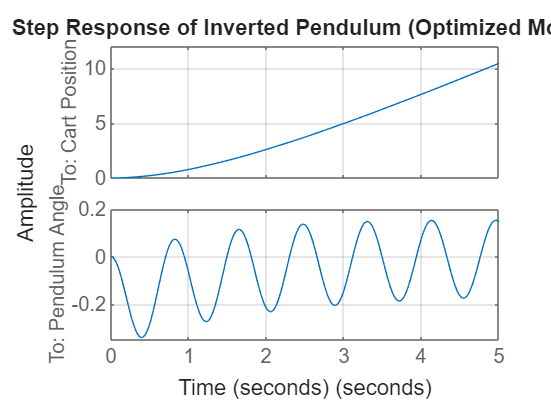

sys_opt.OutputName = {'Cart Position', 'Pendulum Angle'};
t = 0:0.01:5;
% Plot the step response
figure;
step(sys_opt,t);
grid on;
title('Step Response of Inverted Pendulum (Optimized Model)');
xlabel('Time (seconds)');

% ylabel('Cart Position');

n = size(A_opt,1);

% Eigenvalues
eig(A_opt)

ans =    0.0000 + 0.0000i
  -0.6362 + 0.0000i
  -0.0365 + 7.5875i
  -0.0365 - 7.5875i


% Controllability
rank(ctrb(A_opt,B_opt))

ans = 4

% Observability
rank(obsv(A_opt,C_mat))

ans = 4


if rank(ctrb(A_opt,B_opt)) == n
    disp('System is controllable (full rank)')
else
    disp('System is NOT controllable')
end

System is controllable (full rank)



if rank(obsv(A_opt,C_mat)) == n
    disp('System is observable (full rank)')
else
    disp('System is NOT observable')
end

System is observable (full rank)


% %% 1. Discretization
% Ts = 0.01; % 100Hz sampling
% sys_d = c2d(ss(A_opt, B_opt, C_mat, D_mat), Ts,'zoh');
% 
% % 2. Improved Q Matrix (Add damping to velocities)
% Q = C_mat'*C_mat
% R = 1;
% 
% % 3. Discrete LQR Gain
% Kd = dlqr(sys_d.A, sys_d.B, Q, R);
% 
% % 4. Discrete Closed-Loop System
% % x[k+1] = (Ad - Bd*Kd)x[k] + Bd*r[k]
% sys_cl_d = ss(sys_d.A - sys_d.B*Kd, sys_d.B, sys_d.C, sys_d.D, Ts);
% 
% % 5. Simulation
% t = 0:Ts:3;
% r = 0.2 * ones(size(t)); % 0.2m step input for cart position
% [y, t, x] = lsim(sys_cl_d, r, t);
% 
% % 6. Plotting
% figure('Color', 'w');
% subplot(2,1,1);
% plot(t, y(:,1), 'LineWidth', 2); grid on;
% ylabel('Cart Position (m)');
% title('Discrete LQR Step Response (Ts = 10ms)');
% 
% subplot(2,1,2);
% plot(t, y(:,2), 'r', 'LineWidth', 2); grid on;
% ylabel('Pendulum Angle (rad)');
% xlabel('Time (s)');

แก้

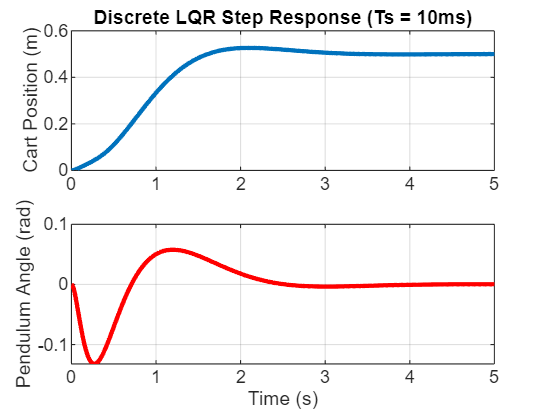

Ts = 0.01; % 100Hz sampling
sys_d = c2d(ss(A_opt, B_opt, C_mat, D_mat), Ts,'zoh');
Ad = sys_d.A;
Bd = sys_d.B;
Cd = C_mat;
Dd = D_mat;

% Q = diag([1550 1 10 1]);
Q = diag([1000 5 2000 100]);
R = 50;
Kd = dlqr(sys_d.A, sys_d.B, Q, R);

F = 1 / (Cref * ((eye(size(Ad)) - (Ad - Bd*Kd)) \ Bd)); % feed forward
sys_cl_d = ss(Ad - Bd*Kd, Bd*F, Cd, Dd, Ts);

% 5. Simulation
t = 0:Ts:5;
v = 0.5 * ones(size(t)); 
[y, t, x] = lsim(sys_cl_d, v, t);

% 6. Plotting
figure('Color', 'w');
subplot(2,1,1);
plot(t, y(:,1), 'LineWidth', 2); grid on;
ylabel('Cart Position (m)');
title('Discrete LQR Step Response (Ts = 10ms)');

subplot(2,1,2);
plot(t, y(:,2), 'r', 'LineWidth', 2); grid on;
ylabel('Pendulum Angle (rad)');
xlabel('Time (s)');


info_x = stepinfo(y(:,1), t, 0.2);
ess_x = abs(0.2 - y(end,1));
fprintf("Settling time X = %.4f\n", info_x.SettlingTime);

Settling time X = NaN


fprintf("Rise time X = %.4f\n", info_x.RiseTime);

Rise time X = 0.5214


fprintf("steaady state err theta = %.4f\n", ess_x);

steaady state err theta = 0.2998



theta = y(:,2);
max_theta = max(abs(theta)); 
ess_theta = abs(0 - theta(end));   
idx = find(abs(theta) > 0.02 * max_theta, 1, 'last');
if isempty(idx)
    settling_theta = 0;
else
    settling_theta = t(idx);
end
fprintf("Settling time theta = %.4f\n", settling_theta);

Settling time theta = 3.3900


fprintf("max_theta = %.4f\n", max_theta);

max_theta = 0.1321


fprintf("steady state err theta = %.4f\n", ess_theta);

steady state err theta = 0.0002


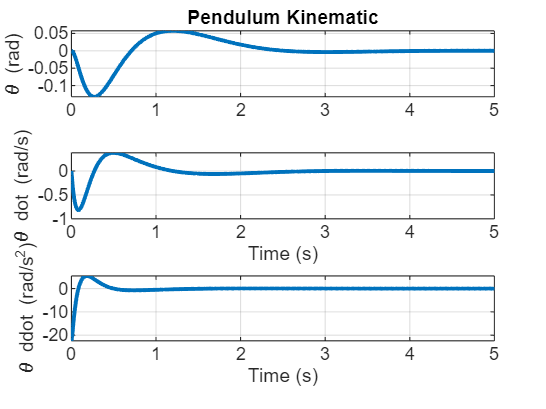

%% After LQR simulation
X      = x(:,1);
X_dot  = x(:,2);
Theta  = x(:,3);
Theta_dot = x(:,4);

% numerical acceleration
X_ddot     = gradient(X_dot, Ts);
Theta_ddot = gradient(Theta_dot, Ts);

% actual control input for LQR
u_LQR = -x*Kd' + F*v';

% theta reference = 0
r_theta = zeros(size(t));
e_theta = r_theta - Theta;

% PLOT
% cart kinematic
figure('Color','w');
subplot(3,1,1)
plot(t, X, 'LineWidth', 1.8); grid on;
ylabel('X (m)');
title('Cart Kinematic');
subplot(3,1,2)
plot(t, X_dot, 'LineWidth', 1.8); grid on;
ylabel('X dot (m/s)');
subplot(3,1,3)
plot(t, X_ddot, 'LineWidth', 1.8); grid on;
ylabel('X ddot (m/s^2)');

% pendulum kinematic
subplot(3,1,1)
plot(t, Theta, 'LineWidth', 1.8); grid on;
ylabel('\theta (rad)');
title('Pendulum Kinematic');
subplot(3,1,2)
plot(t, Theta_dot, 'LineWidth', 1.8); grid on;
ylabel('\theta dot (rad/s)');
xlabel('Time (s)');
subplot(3,1,3)
plot(t, Theta_ddot, 'LineWidth', 1.8); grid on;
ylabel('\theta ddot (rad/s^2)');
xlabel('Time (s)');

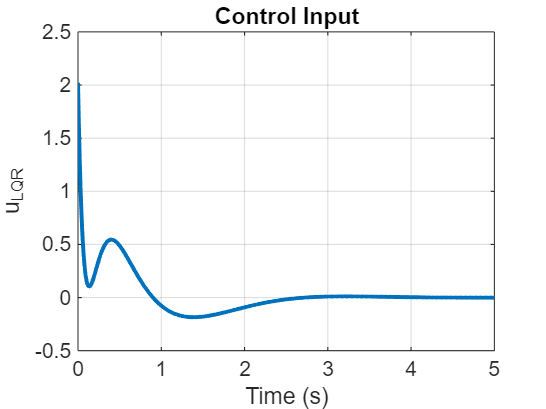


% control input
figure('Color','w');
plot(t, u_LQR, 'LineWidth', 1.8); 
grid on;
ylabel('u_{LQR}');
xlabel('Time (s)');
title('Control Input');

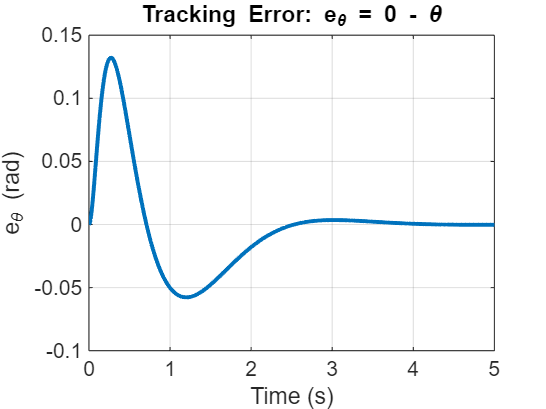


% track err
figure('Color','w');
plot(t, e_theta, 'LineWidth', 1.8); 
grid on;
ylabel('e_\theta (rad)');
xlabel('Time (s)');
title('Tracking Error: e_\theta = 0 - \theta');

Luenberger observer

Acl = Ad-Bd*Kd;
eig(Acl) % real part of discrete sys must < 1

ans =    0.9143 + 0.0585i
   0.9143 - 0.0585i
   0.9790 + 0.0561i
   0.9790 - 0.0561i


p = [-9 -10 -11 -12];
pd = exp(10*p*Ts)

pd =     0.4066    0.3679    0.3329    0.3012


L = place(Ad',Cd',pd)'

L =     1.2936    0.0354
   41.4399    2.3034
    0.0715    1.2850
    6.2580   40.7376



Ace = [(Ad-Bd*Kd) (Bd*Kd);
       zeros(size(Ad)) (Ad-L*Cd)];
Bce = [Bd*F;
       zeros(size(Bd))];
Cce = [Cd zeros(size(Cd))];
Dce = [0;0];

states = {'x' 'x_dot' 'phi' 'phi_dot' 'e1' 'e2' 'e3' 'e4'};
inputs = {'r'}; % v
outputs = {'x'; 'theta'};
% ss(Ad - Bd*Kd, Bd*Nbar, Cd, Dd, Ts);
sys_ce = ss(Ace,Bce,Cce,Dce,Ts,'statename',states,'inputname',inputs,'outputname',outputs);
abs(eig(Acl))

ans =     0.9162
    0.9162
    0.9806
    0.9806


abs(eig(Ad - L*Cd))

ans =     0.4066
    0.3679
    0.3012
    0.3329


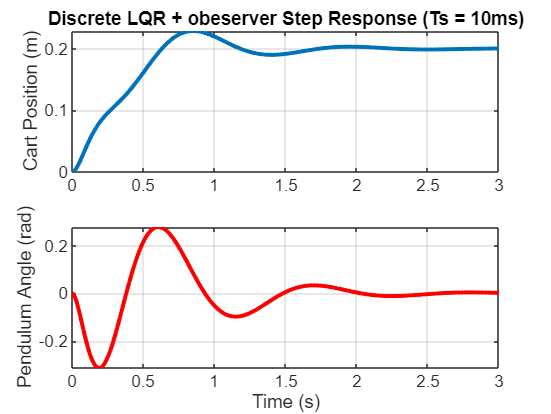


t = 0:Ts:3;
v = 0.2 * ones(size(t)); % 0.2 step input for cart position
[y,t,x] = lsim(sys_ce,v,t);
% x0_ce = [0;0;0;0;   0.5;0;0.01;0]; % [x; e]
% [y,t,x] = lsim(sys_ce,r,t,x0_ce);

figure('Color', 'w');
subplot(2,1,1);
plot(t, y(:,1), 'LineWidth', 2); grid on;
ylabel('Cart Position (m)');
title('Discrete LQR + obeserver Step Response (Ts = 10ms)');

subplot(2,1,2);
plot(t, y(:,2), 'r', 'LineWidth', 2); grid on;
ylabel('Pendulum Angle (rad)');
xlabel('Time (s)');


% figure;
% plot(t, x(:,5:8), 'LineWidth', 1.5);
% grid on;
% xlabel('Time (s)');
% ylabel('Estimation error');
% legend('e_x','e_xdot','e_\theta','e_\thetadot');
% title('Observer Error Dynamics');

kalman filter

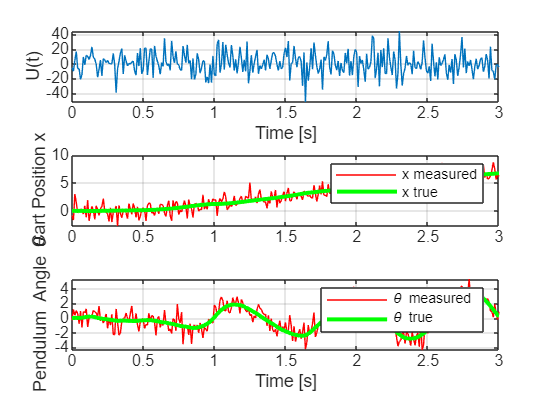

% signal gen
% process noise (model uncertainty)
% measurement noise (sensor noise)
Ts = 0.01; % 100Hz sampling
t = 0:Ts:3;

sigma_w = 100*0.15; % process noise std = disturbance
sigma_v = 10*0.1;   % measurement noise std
u = 0.2 * ones(size(t)); % input fed into KF
W = sigma_w * randn(size(t)); % process noise

[y,t,x] = lsim(sys_d, u + W, t);
y_measured = y + sigma_v*randn(size(y));
% y_measured(:,1) = cart position x
% y_measured(:,2) = pendulum angle theta

figure;
subplot(3,1,1);
plot(t, u + W); xlabel('Time [s]'); ylabel('U(t)'); grid on;
subplot(3,1,2);
plot(t, y_measured(:,1), 'r'); hold on;
plot(t, y(:,1), 'g', 'LineWidth', 2);
legend('x measured','x true');
ylabel('Cart Position x');
grid on;
subplot(3,1,3);
plot(t, y_measured(:,2), 'r'); hold on;
plot(t, y(:,2), 'g', 'LineWidth', 2);
legend('\theta measured','\theta true');
ylabel('Pendulum Angle \theta');
xlabel('Time [s]');
grid on;

% Kalman filter design
% Noise enters through Bd (same channel as input)
Bw = Bd;
% Build KF model
% -> [u_clean; w] as inputs
% -> Bw models noise channel
ss_kf = ss(Ad,[Bd Bw],Cd,[Dd zeros(2,1)],Ts);

% Q = var(W) and R = var(V)
Q_kf = 1*sigma_w^2;
R_kf = 10*sigma_v^2*eye(2);
% Find KF SS
sensors = [1 2];   % measure x and theta
known   = 1;       % first input is known input u
[kalmf,L,P,Mx,Z] = kalman(ss_kf, Q_kf, R_kf, [], sensors, known);

disp('Kalman Gain F_s'); disp(L);

Kalman Gain F_s
    0.0323   -0.0043
    0.0516   -0.0498
   -0.0036    0.0603
    0.0202    0.1422



disp('Prediction Cov M'); disp(Mx);

Prediction Cov M
    0.0318   -0.0038
    0.0521   -0.0509
   -0.0038    0.0587
    0.0161    0.1784



disp('Filter Cov Z');    disp(Z);

Filter Cov Z
    0.3180    0.5206   -0.0375    0.1613
    0.5206    2.3125   -0.5088   -4.4033
   -0.0375   -0.5088    0.5872    1.7843
    0.1613   -4.4033    1.7843   47.7330



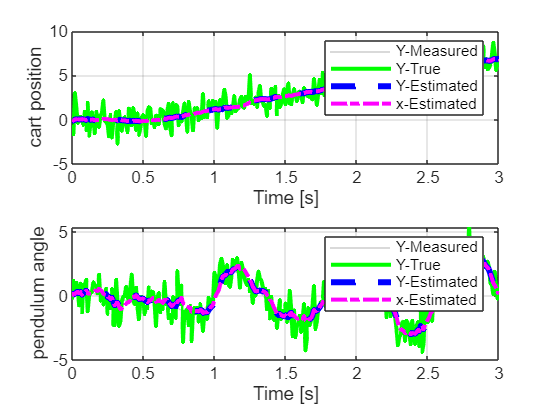

% Calculate y_hat, x_hat
output = lsim(kalmf, [u(:) y_measured],t);
y_hat = output(:,1:2);
x_hat = output(:,3:6);

figure;
subplot(2,1,1);
plot(t, y(:,1),'Color',0.8*[1 1 1]); hold on;
plot(t, y_measured(:,1), 'g','LineWidth',2);
plot(t, y_hat(:,1),  'b--','LineWidth',3);
plot(t, x_hat(:,1), 'm-.','LineWidth',2);
legend('Y-Measured','Y-True','Y-Estimated','x-Estimated');
xlabel('Time [s]'); ylabel('cart position'); grid on;

subplot(2,1,2);
plot(t, y(:,2),'Color',0.8*[1 1 1]); hold on;
plot(t, y_measured(:,2), 'g','LineWidth',2);
plot(t, y_hat(:,2),  'b--','LineWidth',3);
plot(t, x_hat(:,3), 'm-.','LineWidth',2);
legend('Y-Measured','Y-True','Y-Estimated','x-Estimated');
xlabel('Time [s]'); ylabel('pendulum angle'); grid on;

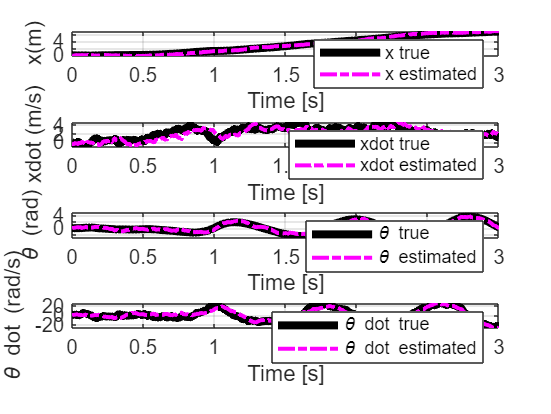

figure;
subplot(4,1,1);
plot(t, x(:,1),'k','LineWidth',4); hold on;
plot(t, x_hat(:,1),'m-.','LineWidth',2);
legend('x true','x estimated'); grid on;
xlabel('Time [s]'); ylabel('x(m)');
set(gca,'FontSize',10);

subplot(4,1,2);
plot(t, x(:,2),'k','LineWidth',4); hold on;
plot(t, x_hat(:,2),'m-.','LineWidth',2);
legend('xdot true','xdot estimated'); grid on;
xlabel('Time [s]'); ylabel('xdot (m/s)');
set(gca,'FontSize',10);

subplot(4,1,3);
plot(t, x(:,3),'k','LineWidth',4); hold on;
plot(t, x_hat(:,3),'m-.','LineWidth',2);
legend('\theta true','\theta estimated'); grid on;
xlabel('Time [s]'); ylabel('\theta (rad)');
set(gca,'FontSize',10);

subplot(4,1,4);
plot(t, x(:,4),'k','LineWidth',4); hold on;
plot(t, x_hat(:,4),'m-.','LineWidth',2);
legend('\theta dot true','\theta dot estimated'); grid on;
xlabel('Time [s]'); ylabel('\theta dot (rad/s)');
set(gca,'FontSize',10);